# **Задание №5.1.** 

**Символьное и численное решение обыкновенного дифференциального**

 **уравнения первого порядка при заданном начальном условии **

**(задача Коши)**

**1.** Найти с помощью символьной математики (Symbolic Math Toolbox) явное решение дифференциального уравнения первого порядка,    


$$\frac{\mathrm{dx}}{\mathrm{dy}}=f\left(t,y\right)$$


если таковое существует, при заданном начальном условии  y0= y(0), т.е. найти точное решение задачи Коши.


$$f\left(t,y\right)=t^2 ∗\mathrm{cos}\text{ }y+0\ldotp 1,{\text{ }y}_0 =0$$


syms y(t)
eqn = diff(y, t) == t.^2 * cos(y) + 0.1;
cond = y(0) == 0;
zex(t) = dsolve(eqn,cond)

 
zex(t) =
 
[ empty sym ]
 


%Решения не существует

**2.** Это же дифференциальное уравнение  при заданном начальном условии  y0= y(0)   решить **численно** (методом Рунге-Кутта 4-го порядка) на заданном интервале [0; 1], используя решатели ode45, ode23, ode113.

**3.** Построить графики решений, вывести таблицу значений независимой переменной t и соответствующих значений функции *y*. 

**4.** Сравнить три решателя ode45, ode23, ode113 по времени вычисления (используя команду **tic****,****toc**), по количеству вычислений  *N* и по точности полученных результатов. Вывести результаты на общий график. 

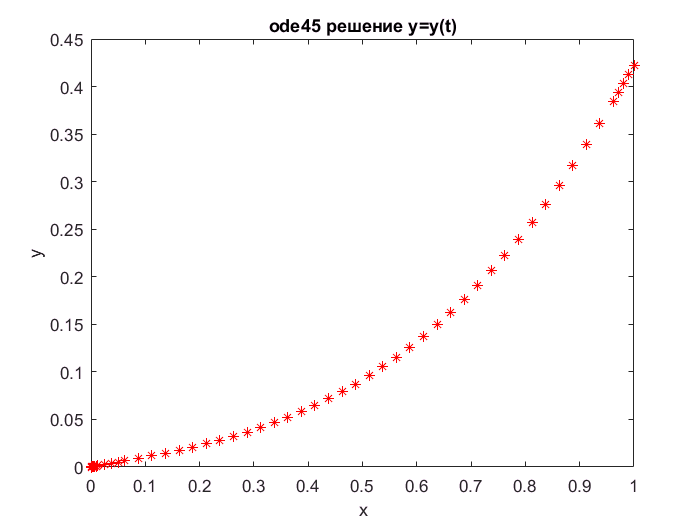

% Для ode45
tic
[t, y] = ode45(@(t, y) t.^2 * cos(y) + 0.1, [0 1], [0]);
time1 = toc;
figure
plot(t, y, 'r*');
title('ode45 решение y=y(t)');
xlabel('x');
ylabel('y');

ode45_N=length(t)

ode45_N = 53

tab = table;
tab.T = t;
tab.Y = y;
tab

tab = 53×2 table
        T             Y     
    __________    __________

             0             0
    0.00050238    5.0238e-05
     0.0010048    0.00010048
     0.0015071    0.00015071
     0.0020095    0.00020095
     0.0045214    0.00045217
     0.0070333    0.00070344
     0.0095452    0.00095481
      0.012057     0.0012063
      0.024616     0.0024666
      0.037176     0.0037347
      0.049735     0.0050145
      0.062295     0.0063101
      0.087295     0.0089512
       0.11229      0.011701
       0.13729      0.014592
       0.16229      0.017654
       0.18729      0.020919
       0.21229      0.024418
       0.23729      0.028182
       0.26229      0.032243
       0.28729      0.036631
       0.31229      0.041377
       0.33729      0.046513
       0.36229       0.05207
       0.38729      0.058078
       0.41229      0.064567
       0.43729      0.071569
       0.46229      0.079114
       0.48729 

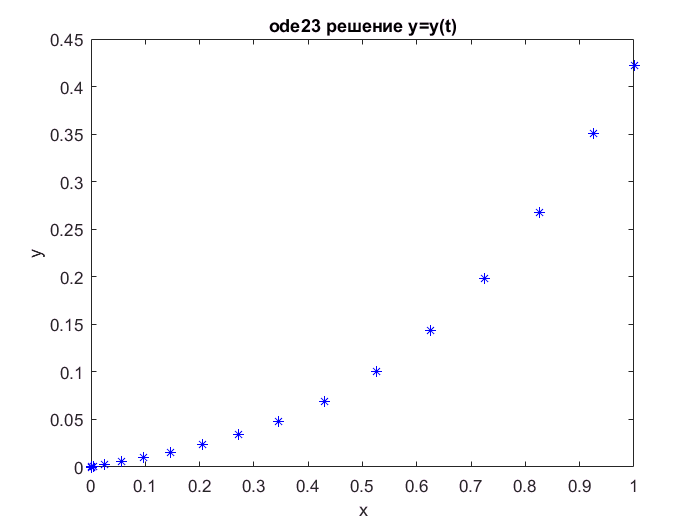

%Для ode23
tic
[t1, y1] = ode23(@(t, y) t.^2 * cos(y) + 0.1, [0 1], [0]);
time2 = toc;
figure
plot(t1, y1, 'b*');
title('ode23 решение y=y(t)');
xlabel('x');
ylabel('y');

ode23_N=length(t1)

ode23_N = 17

tab = table;
tab.T1 = t1;
tab.Y1 = y1;
tab

tab = 17×2 table
       T1           Y1    
    ________    __________

           0             0
      0.0008         8e-05
      0.0048    0.00048004
      0.0248     0.0024851
    0.056057     0.0056644
    0.097192      0.010025
     0.14695      0.015753
     0.20481      0.023345
      0.2708      0.033697
     0.34542      0.048273
      0.4297      0.069386
     0.52522       0.10071
     0.62522       0.14363
     0.72522       0.19863
     0.82522       0.26717
     0.92522        0.3502
           1       0.42188


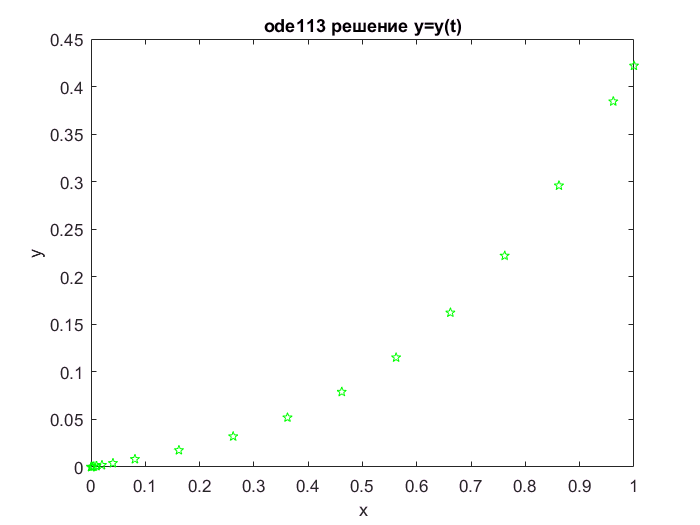

%Для ode113
tic
[t2, y2] = ode113(@(t, y) t.^2 * cos(y) + 0.1, [0 1], [0]);
time3 = toc;
figure
plot(t2, y2, 'gp');
title('ode113 решение y=y(t)');
xlabel('x');
ylabel('y');

ode113_N=length(t2)

ode113_N = 21

tab = table;
tab.T2 = t2;
tab.Y2 = y2;
tab

tab = 21×2 table
        T2            Y2    
    __________    __________

             0             0
    7.9057e-05    7.9057e-06
    0.00023717    2.3717e-05
     0.0005534     5.534e-05
     0.0011859    0.00011859
     0.0024508    0.00024508
     0.0049806     0.0004981
       0.01004     0.0010044
       0.02016     0.0020187
      0.040398     0.0040618
      0.080875     0.0082639
       0.16183      0.017596
       0.26183      0.032164
       0.36183      0.051963
       0.46183      0.078969
       0.56183       0.11512
       0.66183       0.16227
       0.76183       0.22208
       0.86183       0.29585
       0.96183       0.38428
             1       0.42188


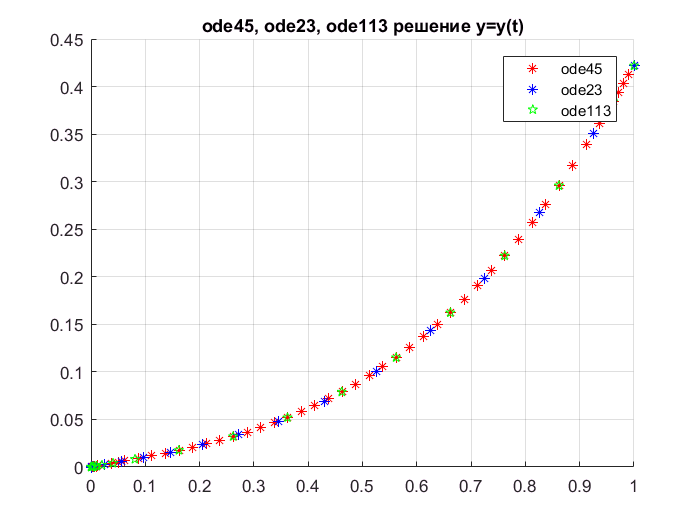

figure;
hold on;
grid on;
title('ode45, ode23, ode113 решение y=y(t)');
plot(t, y, 'r*');
plot(t1, y1, 'b*');
plot(t2, y2, 'gp');
legend('ode45', 'ode23', 'ode113');

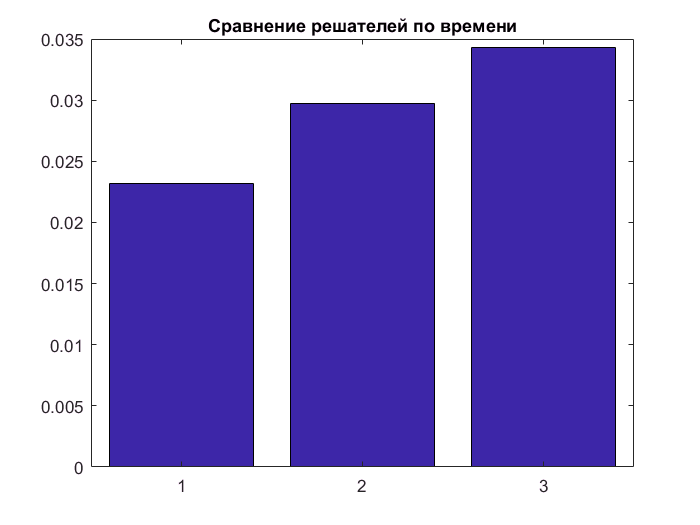

% Сравнение по времени
bb = [time1; time2; time3];
figure
bar(bb);
title('Сравнение решателей по времени');

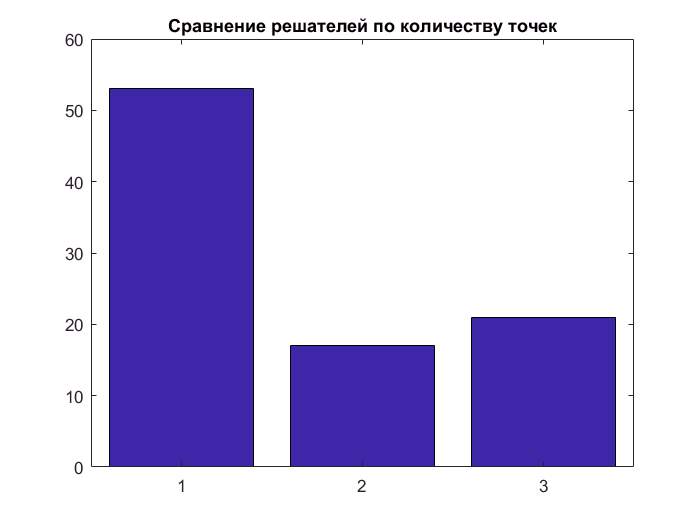

bb = [ode45_N; ode23_N; ode113_N];
figure
bar(bb);
title('Сравнение решателей по количеству точек');

**5.** Выполнить интерполяцию решений для 10 одинаковых моментов времени, равномерно распределенных в заданном интервале [0,1]. Сравнить решения графически и с помощью таблицы, используя для вывода таблицы структуру table.

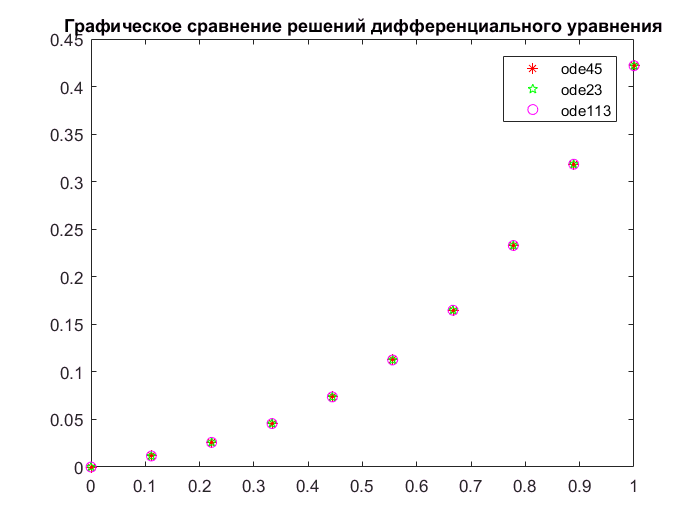

sol1 = ode45(@(t, y) t.^2 * cos(y) + 0.1, [0 1], [0]);
sol2 = ode23(@(t, y) t.^2 * cos(y) + 0.1, [0 1], [0]);
sol3 = ode113(@(t, y) t.^2 * cos(y) + 0.1, [0 1], [0]);
m = 10;
t0 = 0;
t1 = 1;
t = linspace(t0, t1, m);
y1=deval(sol1, t, 1);
y2=deval(sol1, t, 1);
y3=deval(sol2, t, 1);
plot(t, y1, 'r*', t, y2, 'gp', t, y3, 'mo');
title('Графическое сравнение решений дифференциального уравнения');
legend('ode45','ode23','ode113');

tab = table;
N = 1:m;
tab.N = N';
tab.Time = t';
tab.ode45 = y1';
tab.ode23 = y2';
tab.ode113 = y3';
tab

tab = 10×5 table
    N      Time       ode45       ode23       ode113 
    __    _______    ________    ________    ________

     1          0           0           0           0
     2    0.11111    0.011568    0.011568    0.011568
     3    0.22222     0.02588     0.02588     0.02588
     4    0.33333    0.045672    0.045672    0.045672
     5    0.44444     0.07367     0.07367    0.073671
     6    0.55556     0.11255     0.11255     0.11255
     7    0.66667     0.16486     0.16486     0.16487
     8    0.77778     0.23289     0.23289     0.23289
     9    0.88889     0.31832     0.31832     0.31833
    10          1     0.42188     0.42188     0.42188
